# Condiționarea matricei lui Hilbert

Matricea lui Hilbert de ordinul $n$ este matricea $H_n=(h_{ij})$, $i,j=1,\dots,n$

$h_{ij}=\frac{1}{i+j-1}$. De exemplu, $H_4$ este


sym(hilb(4))

$$ans = \left(\begin{array}{cccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6}\\ \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} \end{array}\right)$$

Matricea Hilbert este simetrică și pozitiv definită, deci nesingulară.

Elementele inversei $H_n^{-1}$ sunt numere întregi, de exemplu $H_4^{-1}$ este

sym(invhilb(4))

$$ans = \left(\begin{array}{cccc} 16 & -120 & 240 & -140\\ -120 & 1200 & -2700 & 1680\\ 240 & -2700 & 6480 & -4200\\ -140 & 1680 & -4200 & 2800 \end{array}\right)$$

Calculează condiționarea matricei Hilbert $cond_{2}(H_{n})$ cu ajutorul valorilor proprii. Se va utiliza formula


$$\mathrm{cond}_{2}(H_n) = \lambda_{\max}(H_n)\lambda_{\max}(H_{n}^{-1})$$


O estimare teoretică, pentru $n$ mare, datorată lui Szegő, este


$$cond_{2}(H_n) \sim \frac{(1+\sqrt{2})^{4n+4}}{2^{15/4}\sqrt{\pi n}}$$


format short e
fprintf(' n      cond2      theoretical\n')

 n      cond2      theoretical


for n=10:10:100
    c = max(eig(hilb(n)))*max(eig(invhilb(n)));
    th = (sqrt(2)+1)^(4*n+4)/(2^(15/4)*sqrt(pi*n));
    fprintf('%3d  %11.4e   %11.4e\n', n,c,th)
end

 10   1.6026e+13    9.2192e+14
 20   2.4522e+28    1.3342e+30
 30   4.2278e+43    2.2294e+45
 40   7.6529e+58    3.9513e+60
 50   1.4229e+74    7.2330e+75
 60   2.6913e+89    1.3513e+91
 70  5.1508e+104   2.5604e+106
 80  9.9444e+119   4.9016e+121
 90  1.9328e+135   9.4578e+136
100  3.7765e+150   1.8363e+152


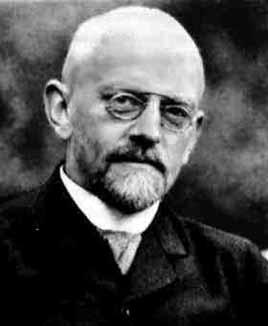       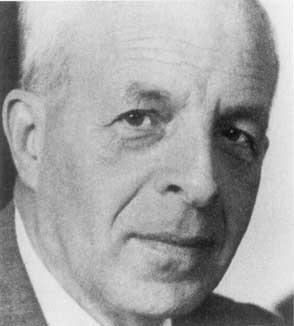

David Hilbert (1862 - 1943)           Gábor Szegő (1895-1985)